**Carlo Colizzi & Daniel Park | ModSim 2020 Final Project**

# **Ball Bouncing Simulation**

### Introduction

For this project, our objective was to investigate *how different materials and launch heights of a ball affect its position tajectory.* We chose this question because although it can be relatively simple to initially model, iterations can allow us to expand into various different topics. We first created a model using the kinematics equations of motion, and then iterated onto modelling it with ODEs, successively adding the two dimensions components together to obtain a projection onto the x-y space. This allowed us to analyse the trends created by the sweeping of some parameters, hence allowing us to gather our results.

## **Question: ***How will different materials and launch heights of a ball affect its position trajectory?*

## **Methodology/Model: **

### Diagrams

In order to accurately answer this question, we first designed two diagrams of our model.

***Schematic and Free-Body-Diagrams***

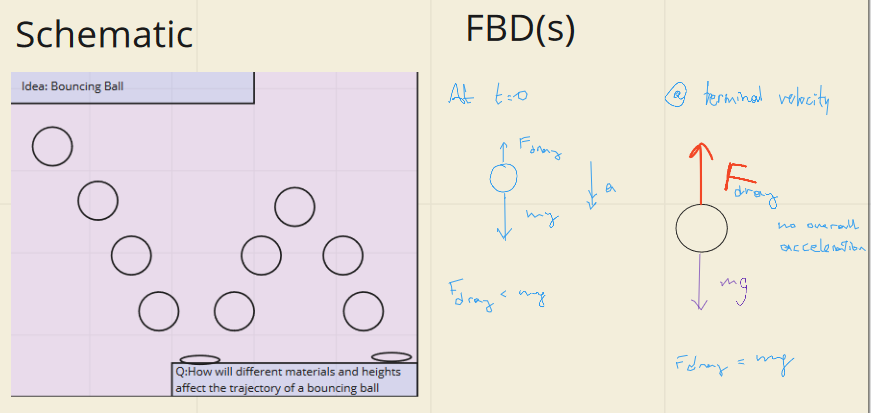

***Stock and Flow Diagram***

The two forces acting on the ball is the force of gravity and the normal force acting against the ground

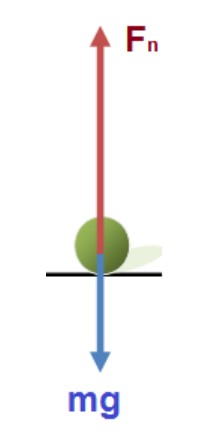

### ODEs

Given the above diagrams, we were able to obtain the following ODEs for motion in the y-dimension:

dv/dt = g

which, in terms of position, translates to:

d^2x/dt^2 = g

We therefore divided this into two different first order ODEs, so it can be later accepted by ode45.

dvdt = g

dydt = v

Regarding motion in the x-dimension, the velocity of an object (ignoring air resistance) is constant throughout its entire motion. 

 x = Vx_0 * t

### Assumptions

In order to accurately model our system, we first had to take a certain number of assumptions.

- air resistance is negligible

- the ball is released from rest in the y-direction (it is not pushed down or up - initial velocity in the y-direction = 0)

- No energy losses due to the deformation of the ground (at an atomic level)

### Ball Launch Simulation

First, we decided to use the kinematic equations of motion to come up with a first iteration of the model

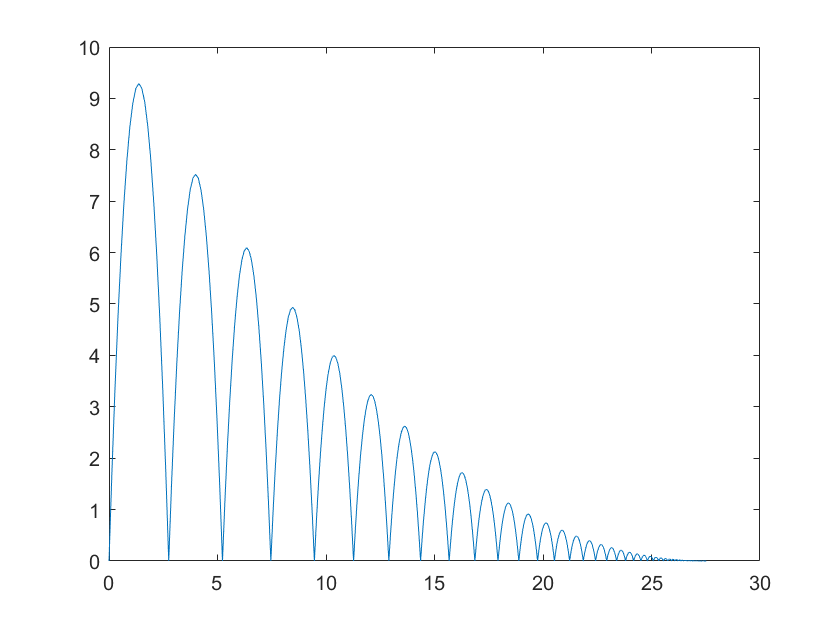

clf
ball_bounce
plot(x,y)

### **ODE45 implementation**

After having develped this model using the kinematic equations, we transferred it to second order differential equations.

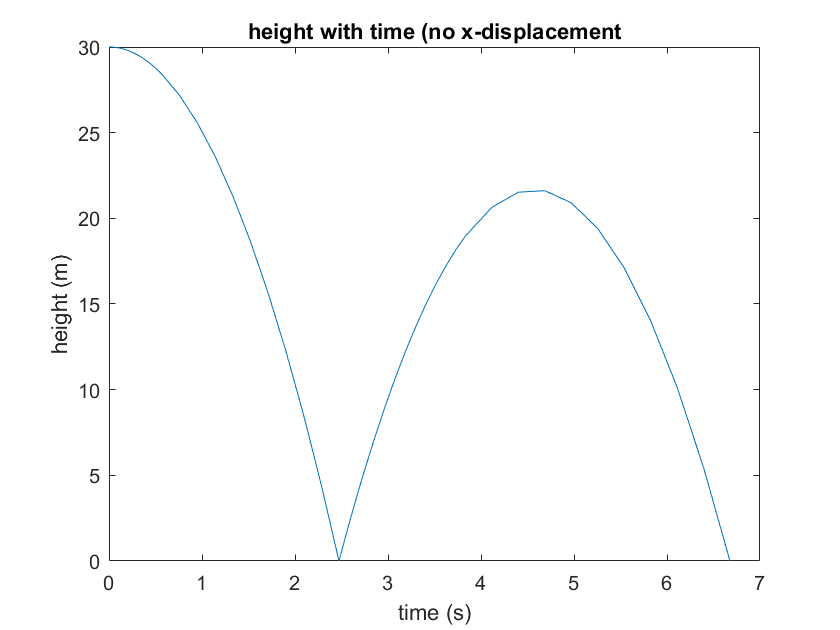

clf; figure;
[T, H] = bouncing_y(30);

plot(T, H(:,1), "-"); % position
xlabel("time (s)")
ylabel("height (m)")
title("height with time (no x-displacement")

During this third iteration, we decided to put our code in a loop to simulate more bounces. We also added the equation for motion in the x-dimension, now plotting displacement in y agains displacement in x.

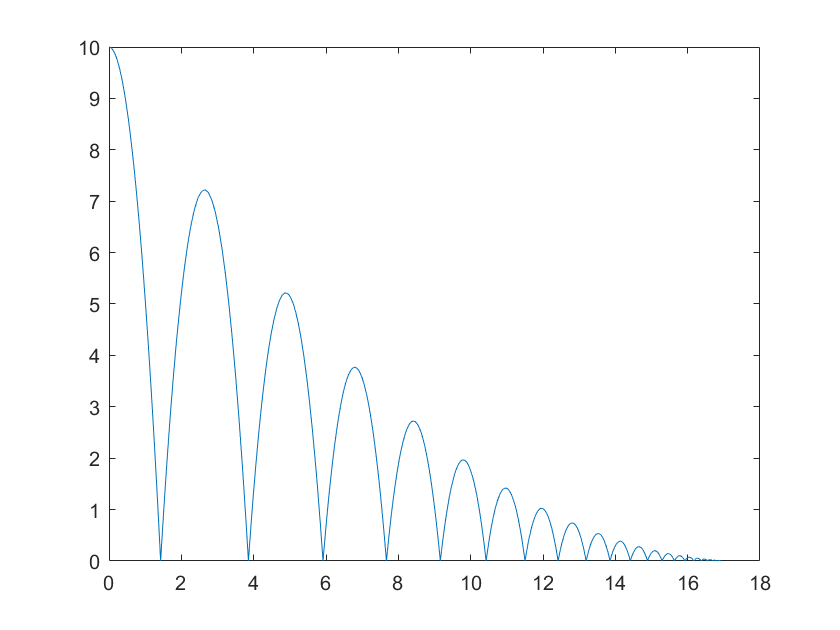

clf; figure;

[x, y] = bouncing_xy(10, 1, 0.85);
plot(x, y(:, 1))

### Sweeping Heights

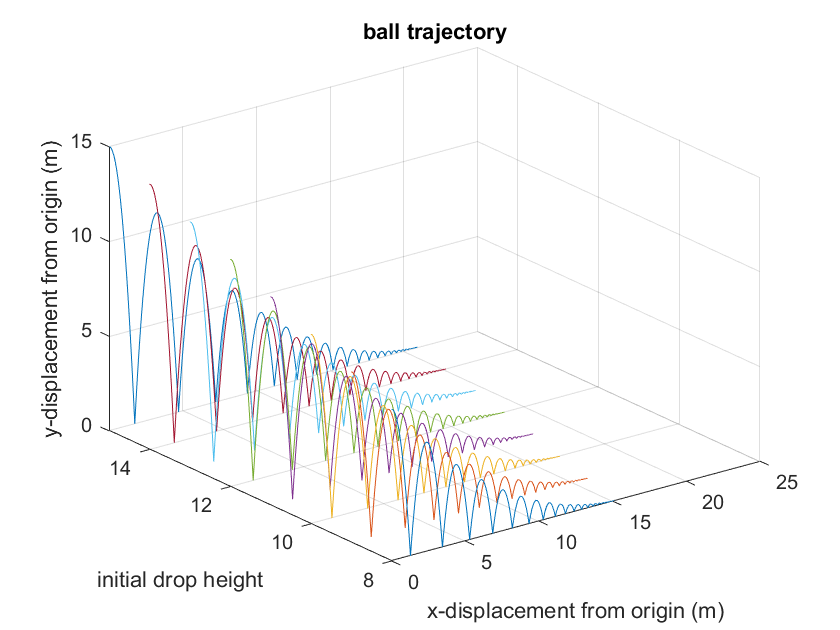

clf; figure
height = [8:1:15];
X = zeros(5000, length(height));
Y = zeros(5000, length(height));
Z = NaN(5000, length(height));

for i = 1:length(height)
[x, y] = bouncing_xy(height(i), 1, 0.85);

X(1:length(x), i) = x;
Y(1:length(y), i) = y(:, 1);
Z(1:length(x), i) = height(i).*ones(size(x(i)));

end

plot3(X, Z, Y); colormap("default"); grid;

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("initial drop height")
title("ball trajectory")

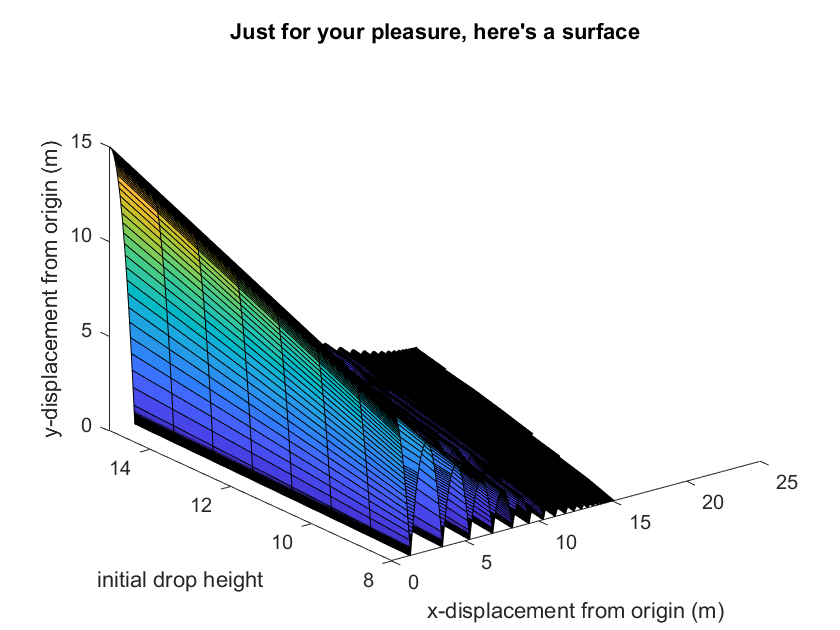


surf(X, Z, Y); colormap("default"); grid;

ylim([height(1), height(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("initial drop height")
title("Just for your pleasure, here's a surface")

Please Note: the gaps that can be seen are due to an incompatibility with surf(), and not errors in calculations.

### Sweeping COR

We proceeded to sweep the other parameter we are investigating: the material of the ball. Different materials mostly affect the ball in just one way: they change how high it bounces. This is determined by the coefficient of restitution, which is 1 for perfectly elastic collisions and under this value for inelastic collisions, where energy is lost to surroundings. 

Below a table of some materials and their COR can be found. 

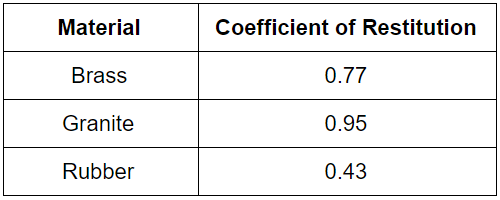

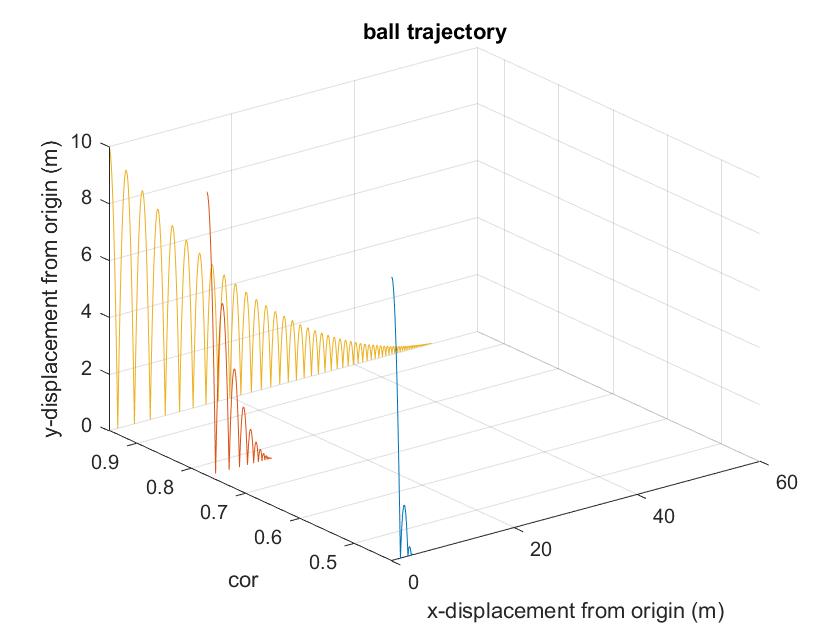

clear;
clf; figure
cor = [0.43, 0.77, 0.95]; %Brass, Granite and Rubber Respectively
X = zeros(5000, length(cor));
Y = zeros(5000, length(cor));
Z = NaN(5000, length(cor));

for i = 1:length(cor)
    [x, y] = bouncing_xy(10, 1, cor(i));
    
    X(1:length(x), i) = x;
    Y(1:length(y), i) = y(:, 1);
    Z(1:length(x), i) = cor(i).*ones(size(x(i)));
end
plot3(X, Z, Y); colormap("default"); grid;

ylim([cor(1), cor(end)])
xlabel("x-displacement from origin (m)")
zlabel("y-displacement from origin (m)")
ylabel("cor")
title("ball trajectory")

## **Results:**

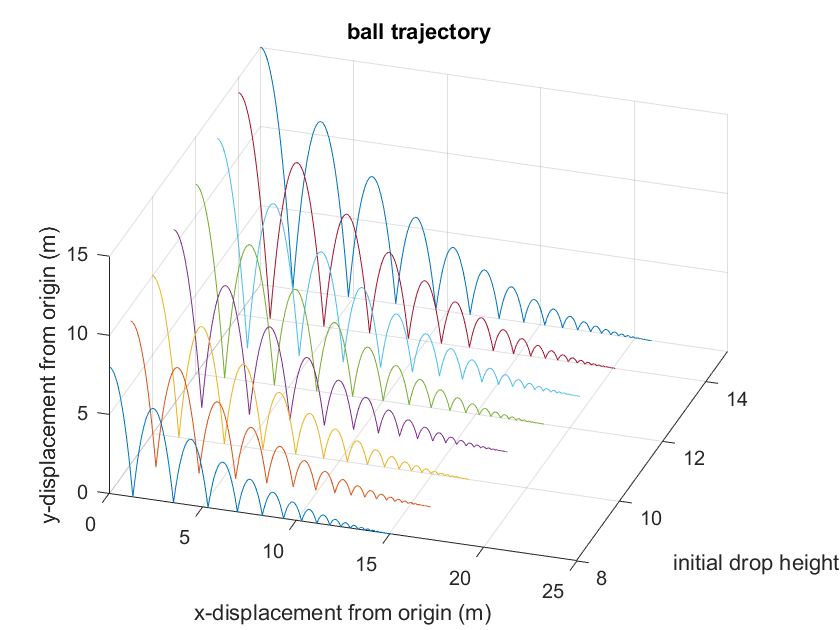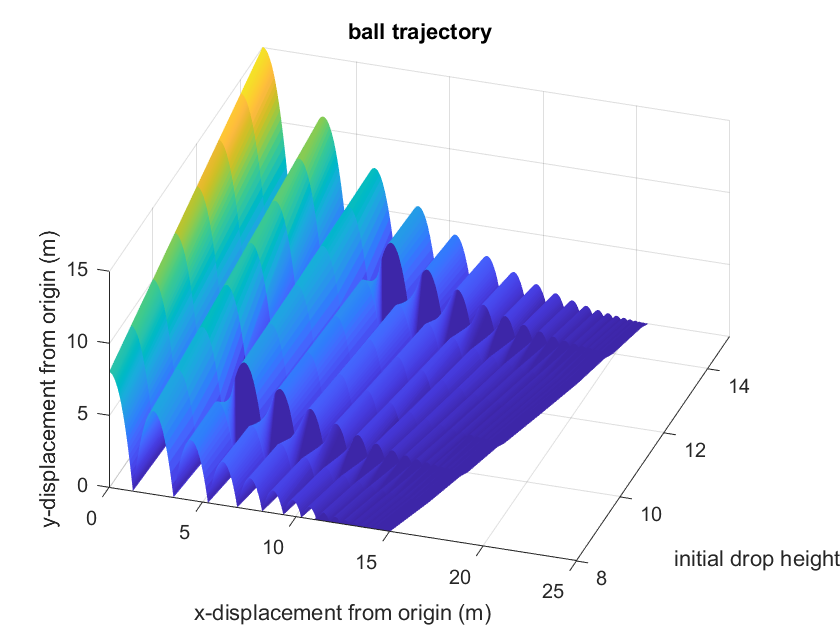

These two graphs are the same thing.

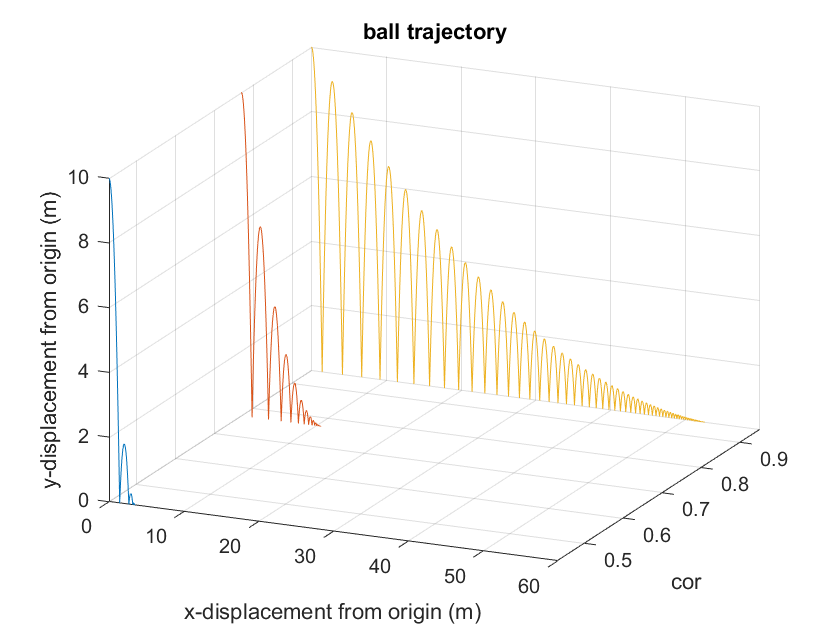

although it is not still here, we can imagine the results, can you please start talking about it? thanks

Talk about validating by interpreting trends?

## **Results:**

## **Interpretation:**

## **Works Cited:**

Team 3_07 Miro Board: [https://miro.com/app/board/o9J_leaToAE=/](https://miro.com/app/board/o9J_leaToAE=/)

Newton's Physics Equations: [https://www.physicsclassroom.com/calcpad/newtlaws](https://www.physicsclassroom.com/calcpad/newtlaws)